## Get Data

filename = '/home/user/ABG/ABG_classification/data/pngs';
[testIMDS,validationIMDS,trainingIMDS] = get_rand_abgo_imds(filename);


## Resize the data

%resize datastore to [224, 224, 3]
train_audIMDS = augmentedImageDatastore([224, 224, 3], trainingIMDS);
validation_audIMDS = augmentedImageDatastore([224, 224, 3], validationIMDS);
test_audIMDS = augmentedImageDatastore([224, 224, 3], testIMDS);

% Important datastores have been resized to fit specified for
% the model
train_audIMDS;
validation_audIMDS;
test_audIMDS;
% end of data split


mobnet_trained = load('TrainedMob.mat');
net = mobnet_trained.net;
%analyzeNetwork(net)    % uncomment to analyze network

% layer 104/154: block_11_add
layer = 'block_11_add';
featuresTrain = activations(net,train_audIMDS,layer);
featuresTest = activations(net,test_audIMDS,layer);
whos featuresTrain

  Name                Size                        Bytes  Class     Attributes

  featuresTrain      14x14x96x7891            593908224  single              




featuresTrain = squeeze(mean(featuresTrain,[1 2]))';
featuresTest = squeeze(mean(featuresTest,[1 2]))';
whos featuresTrain

  Name                  Size              Bytes  Class     Attributes

  featuresTrain      7891x96            3030144  single              



### SVM templates 

% t_1 = templateSVM( ...
%      'Standardize','on', ...
%      'KernelFunction','gaussian' ...
%      );

t1 = templateSVM('BoxConstraint',0.7, ...
   'KernelFunction','rbf', ...
   'DeltaGradientTolerance',1e-2, ...
   'Solver','SMO', ...
   'Standardize',false);

t2 = templateSVM('BoxConstraint',0.475, ...
 'KernelFunction','polynomial', ...
 'DeltaGradientTolerance',1e-3, ...
 'PolynomialOrder',1, ...
 'Solver','ISDA', ...
 'Standardize',true);

t3 = templateSVM('BoxConstraint',0.015, ...
   'KernelFunction','linear', ...
   'DeltaGradientTolerance',1e-2, ...
   'Solver','ISDA', ...
   'Standardize',true);

t4 = templateSVM('BoxConstraint',1, ...
   'KernelFunction','gaussian', ...
   'DeltaGradientTolerance',1e-2, ...
   'Solver','SMO', ...
   'Standardize',false...
   );

template = {t1,t2,t3,t4};

### Classify, Predict, Confusion Matricies and F-Scores

accuracy = 0.8250

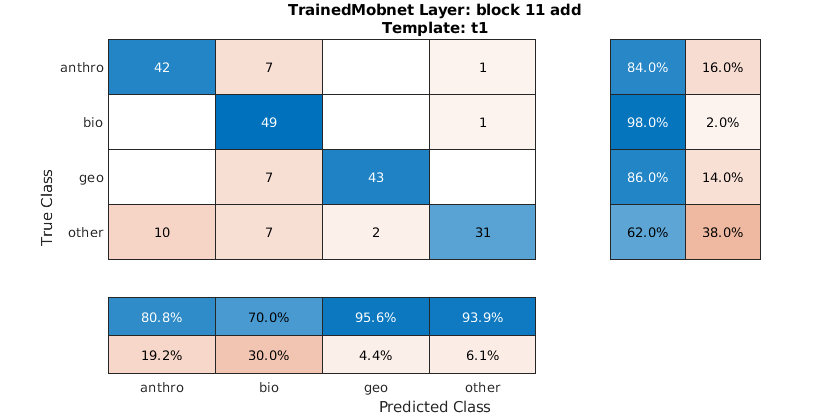

accuracy = 0.8250

fScore =     0.8235    0.8167    0.9053    0.7470


avg_f_score = 0.8231

accuracy = 0.8350

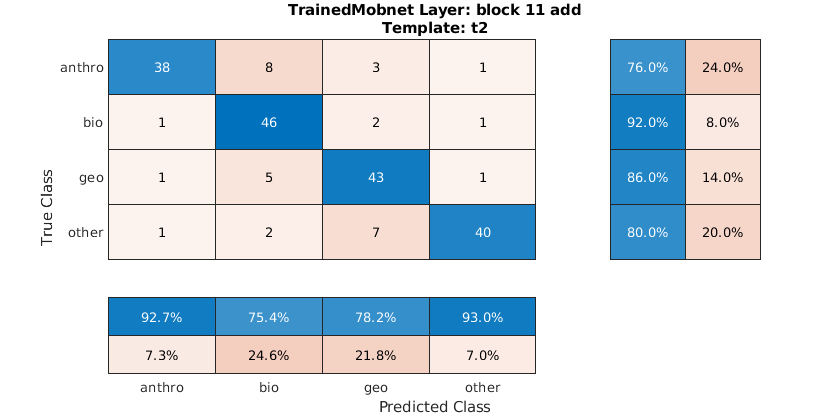

accuracy = 0.8350

fScore =     0.8352    0.8288    0.8190    0.8602


avg_f_score = 0.8358

accuracy = 0.7650

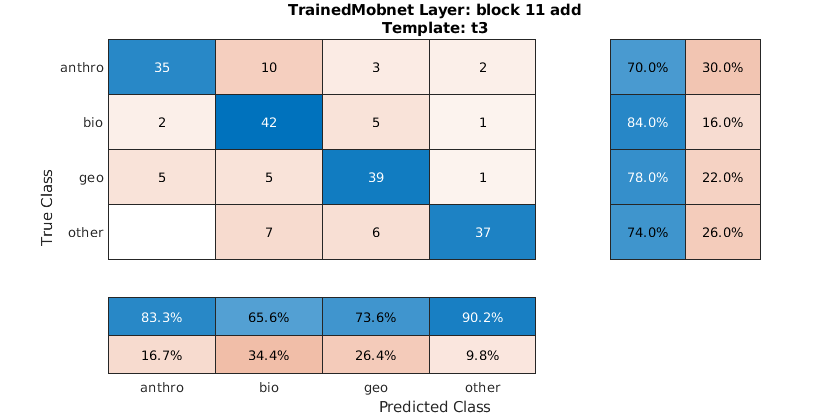

accuracy = 0.7650

fScore =     0.7609    0.7368    0.7573    0.8132


avg_f_score = 0.7670

accuracy = 0.9400

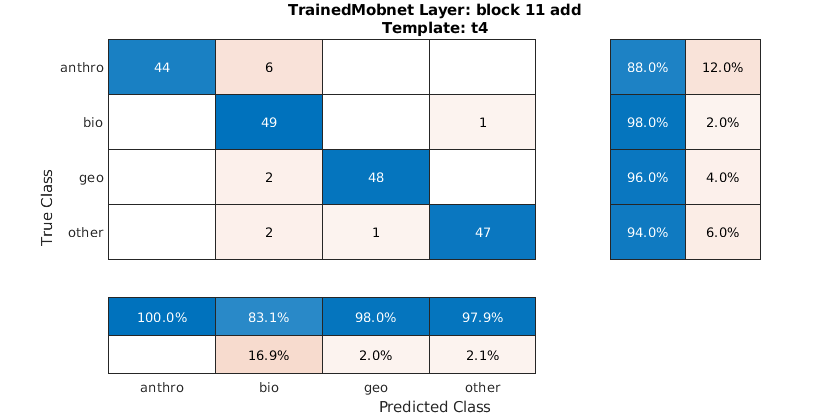

accuracy = 0.9400

fScore =     0.9362    0.8991    0.9697    0.9592


avg_f_score = 0.9410

for i=1:size(template,2)
    classifier = fitcecoc( ...
        featuresTrain, ...
        trainingIMDS.Labels, ...
        'Learners',template(i), ...
        'Options',statset('UseParallel',true) ...
        );
    
    
    YPred = predict(classifier,featuresTest);
    accuracy = mean(YPred == testIMDS.Labels)
    
    % Displaying confusion chart
    fig = figure;
    fig_Position = fig.Position;
    fig_Position(3) = fig_Position(3)*1.5;
    fig.Position = fig_Position;
    cm = confusionchart(testIMDS.Labels,YPred,'RowSummary','row-normalized','ColumnSummary','column-normalized');
    title(cm,{"TrainedMobnet Layer: block 11 add","Template: t"+i})
    
    % Calculating fScore and avg_f_score
    cm1 = cm.NormalizedValues;
    
    for i = 1:size(cm1,1)
        precision(i) = cm1(i,i)/sum(cm1(i,:));
    end
    
    for i = 1:size(cm1,1)
        recall(i) = cm1(i,i)/sum(cm1(:,i));
    end
    
    for i = 1:size(precision,2)
        fScore(i) = (2 * (precision(i) * recall(i)) / (precision(i) + recall(i)));
    end
    
    % Displaying results
    accuracy
    fScore
    avg_f_score = sum(fScore)/numel(fScore)
end